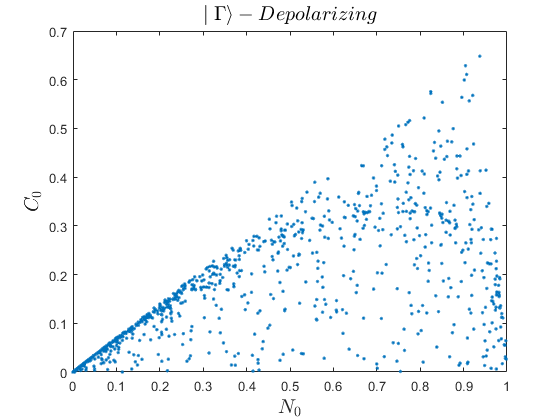

% random=GDeRandomStates(1000)
figure
plot(random(:,1),random(:,2),".")
xlabel("$N_0$","Interpreter","latex","FontSize",15)
ylabel("$C_0$","Interpreter","latex","FontSize",15)
title(strcat("$","\mid \Gamma \rangle-","Depolarizing","$"),"Interpreter","latex","FontSize",15)

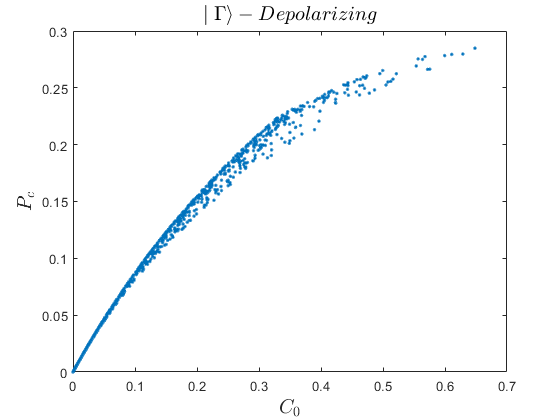

figure
plot(random(:,2),random(:,5),".")
xlabel("$C_0$","Interpreter","latex","FontSize",15)
ylabel("$P_c$","Interpreter","latex","FontSize",15)
title(strcat("$","\mid \Gamma \rangle-","Depolarizing","$"),"Interpreter","latex","FontSize",15)

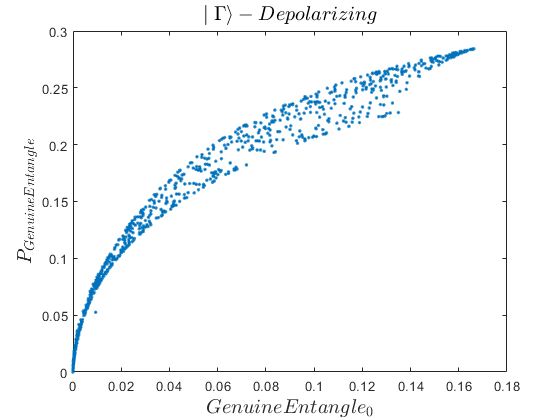

figure
plot(random(:,3),random(:,6),".")
xlabel("$GenuineEntangle_0$","Interpreter","latex","FontSize",15)
ylabel("$P_{GenuineEntangle}$","Interpreter","latex","FontSize",15)
title(strcat("$","\mid \Gamma \rangle-","Depolarizing","$"),"Interpreter","latex","FontSize",15)

% writematrix(random,"Data/Random.xlsx")

function [random]=GDeRandomStates(hits)
theta=linspace(0,pi,hits);phi=linspace(0,2*pi-10^(-16),hits);Y=linspace(0,1-10^(-16),hits);
pN=zeros(hits,1);pC=zeros(hits,1);n0=zeros(hits,1);pW=zeros(hits,1);
c0=zeros(hits,1);w0=zeros(hits,1);
parfor i=1:hits
    disp(i)
    j=ceil(hits*rand)
    k=ceil(hits*rand)
    pN(i)=GDe2P(theta(i),phi(j),Y(k),"Negativity");
    pC(i)=GDe2P(theta(i),phi(j),Y(k),"Concurrence");
    pW(i)=GDe2P(theta(i),phi(j),Y(k),"Witness");
    n0(i)=GDe1Entanglement(0,theta(i),phi(j),Y(k),"Negativity");
    c0(i)=GDe1Entanglement(0,theta(i),phi(j),Y(k),"Concurrence");
    w0(i)=GDe1Entanglement(0,theta(i),phi(j),Y(k),"Witness");
end
random=cat(2,n0,c0,w0,pN,pC,pW);%n,pN,pC
disp("Random State Finished");
end